# **Tutorial 13**: the slider-crank mechanism  ( $\approx 3\;mn$ run)

## 1. Description

The objective of this tutorial is to illustrate on the well-known slider-crack mechanism how it is possible to model closed kinematic chains of rigid or flexible bodies with the `SDTlib` involving prismatic joints. Let us consider the slider-crank mechanism depicted in the following Figure charcaterized by  1 piston $\mathcal P$, 2 uniform flexible bars (the rod $\mathcal R$ of length $l\,(m)$ and the crank $\mathcal C$ with a radius $r\,(m)$ ) in the $\mathbf x, \mathbf y$-plane, a prisamtic joint  along $\mathbf x$-axis and  3 revolute joints around $\mathbf z$-axis.

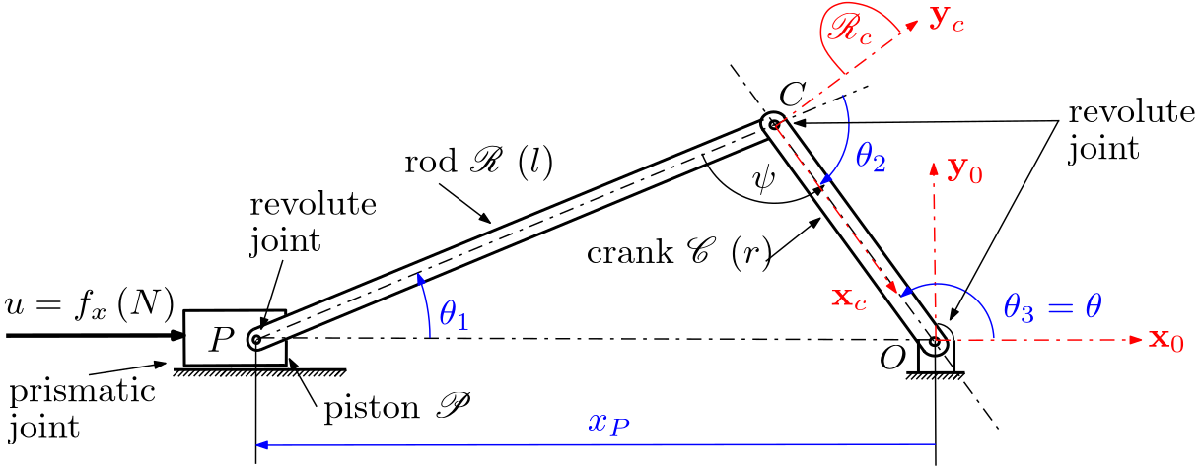

Indeed, as it is mentionned in the [***introduction***](matlab:open('../Tutorial1/tutorial1.html')) (tutorial 1), such a closed kinematic chain have some non-linear loop closure constraints $\mathbf g(\mathbf \theta,\mathbf x_f)=\mathbf 0$ which are not solved in the `SDTlib.`

For this mechanism it is proposed to parametrize the model according to $\theta_3=\theta$. Then:

$x_p=r\cos\theta_3-\sqrt{l^2-r^2\sin^2\theta_3}$,

$\theta_2=\underbrace{\arccos\frac{l^2+r^2-x_p^2}{2lr}}_{\psi}-\pi$,

$\theta_1=\theta_3-\theta_2-\pi$.

**Numerical application:  **The piston has a mass $m_P=1\,Kg$. The rod and the crank are made of aluminium beams with a square cross section of $1\,cm$ side. $l=1\,m$ and $r=0.3\,m$.

% Dynamic parameters
% Piston mass:
mP=1;  %Kg
% Rod and cranck: aluminium beams with square cross section: thickness 1 cm
h=0.01;         % side of the square cross section (m)
rho=2700;       % mass density (Kg/m^3)
S=h^2;          % beam cross seection (m^2)
E=70e9;         % Young module (N/m^2)
ni=0.35;        % Poison coefficient
GG=E/(2*(1+ni));% Shear modulys (N/m^2)
Iz=h^4/12;      % second mooment of aera arount z-axis
Iy=Iz;          % second mooment of aera arount Y-axis
xi=0.005;       % common damping ratio
% Rod:
l=1;            % length (m)
% Cranck:
r=0.3;

Considering the particular case $\theta=3\pi/4$, the loop closure constraints  on $x_P$, $\theta_2$ and $\theta_1$ reads:

% Geometry:
theta3=3*pi/4;
xP=r*cos(theta3)-sqrt(l^2-r^2*sin(theta3)^2)

xP = -1.1894

theta2=acos((l^2+r^2-xP^2)/2/r/l)-pi

theta2 = -0.9992

theta1=theta3-theta2-pi

theta1 = 0.2138

In the next sections the objective is to compute the dynamic model from $f_x=u\,(N)$, the force applied by an actuator on the piston $\mathcal P$ at the point $P$, to:

- the linear acceleration $\ddot x_P$ of the piston. One can then compute the apparent mass $m(\theta)\;(Kg)$ seen from the actuator at point $P$ i.e. the inverse of the DCgain of the transfer $\frac{\ddot X_p}{U}(\mathrm s,\theta)$,

- the angular accelerations $\ddot\theta_1$, $\ddot\theta_2$ and $\ddot\theta_3$. 

- the axial and radial forces $F_{x\mathcal{C}/.,O}$, $F_{y\mathcal{C}/.,O}$ applied by the crank $\mathcal C$ on the ground at point $O$ (along $\mathbf x$-axis and $\mathbf y$-axis, respectively).

## 2. Model

Since the links are considered flexible, it possible to specify 2 independent accelerations twists at 2 different points (see also the section 1.4 of [***tutorial 5***](matlab:open('../Tutorial5/tutorial5.html'))). For that, we need to apply the channel inversion function `invio` to the TITOP model of the flexible link where the loop is closed, here the crank $\mathcal C$ at point $O$, exactly as it was done in the tutorial 11 for the [***4-bar mechanism***](matlab:open('../Tutorial11/tutorial11.html')). **Note also that these channel operations are performed on TITOP model of flexible body where the motion vectors are restricted to the 6 acceleration components.** Indeed, the position and the velocity at 2 different points of a flexible structure, when they are on the inputs of the model due to channel inversions, cannot be independent of the internal deflection positions and rates (internal state variables) and thus are not considered.

Then one can compute the TITOP model $[\mathbf{M}_{C,O}^{\mathcal{C}}]_{\mathcal R_c}(\mathrm s)$ of the crank directly from the mechanical parameters thanks to the function `TwoPOrtBeamFull.`**m** (in the `SDTfct/bib_SDT` sub-directory):

% TITOP model of the cranck:
crank=TwoPortBeamFull(rho,S,r,E,GG,Iz,Iy,xi);

This $12\times 12$  model corresponds to the following block diagram:

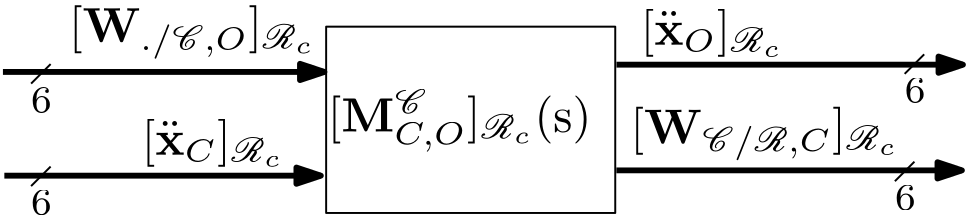

The inversion of the channels # 1,2,3,4,5 and 12 allows to specify that:

- **channels 1 to 5:** the first 5 components of the acceleration twist $\ddot\mathbf x_{O}$ at point $O$ are imposed. These 5 inputs will be set to $0$ in this application to meet the closure constraints. The forces $F_{x\mathcal{C}/.,O}$ and $F_{y\mathcal{C}/.,O}$ to be analyzed corresponds to the outputs # 1 and 2 with a minus sign,

- **channel 6**: the input # 6 is the torque applied inside the revolute joint between the crank anf the ground at point $O$. It will be also set to 0. The output is the revolute joint acceleration $\ddot\theta_3$,

- **channels 7 to 11**: the inputs # 7 to 11 are the first 5 components of the acceleration twist $\ddot\mathbf x_C$ imposed by the rod $\mathcal R$ at point $C$. The outputs are the first 5 components of the wrench $\mathbf{W}_{\mathcal{C}/\mathcal{R},C}$ applied by the crank to the rod at point $C$ (interaction torque around $\mathbf z$-axis cannot be applied due to the revolute joint),

- **channel 12: **the input # 12 is the torque applied inside the revolute joint between the rod and crank at point $C$. It will be also set to $0$. The output is the revolute joint acceleration $\ddot\theta_2$.

This model, named  $[\mathbf{M}_{C,O}^{\mathcal{C}}]^{-1_{[1:5,12]}}_{\mathcal R_c}(\mathrm s)$ can be represented by the following block-diagram:

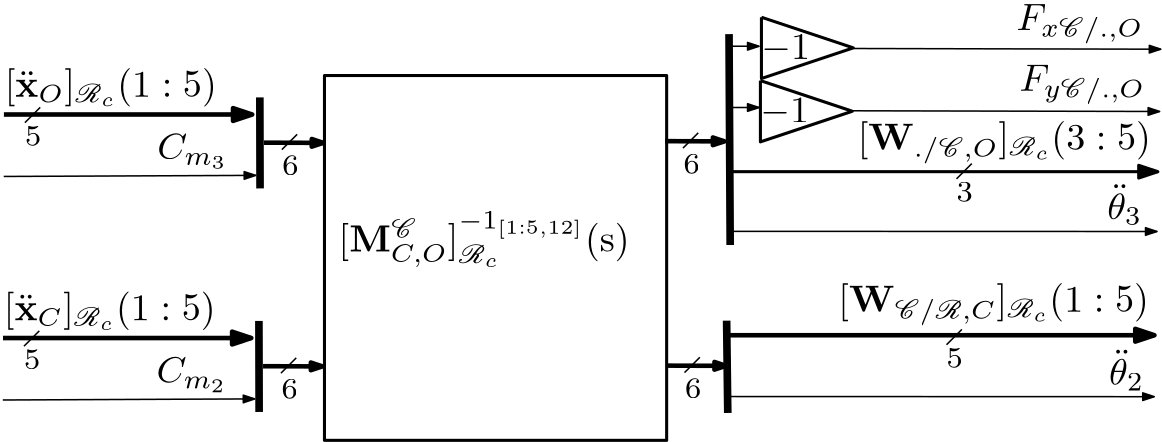

Then the SIMULINK model `SliderCrank.slx` involves this model with:

- 1 block `prismatc joint` for the pîston and its prismatic joint,

- 1 block `TITOP flexible beam + revolute joint`  for the rod,

- the DCMs associated to the frame rotation $\theta_2$,.

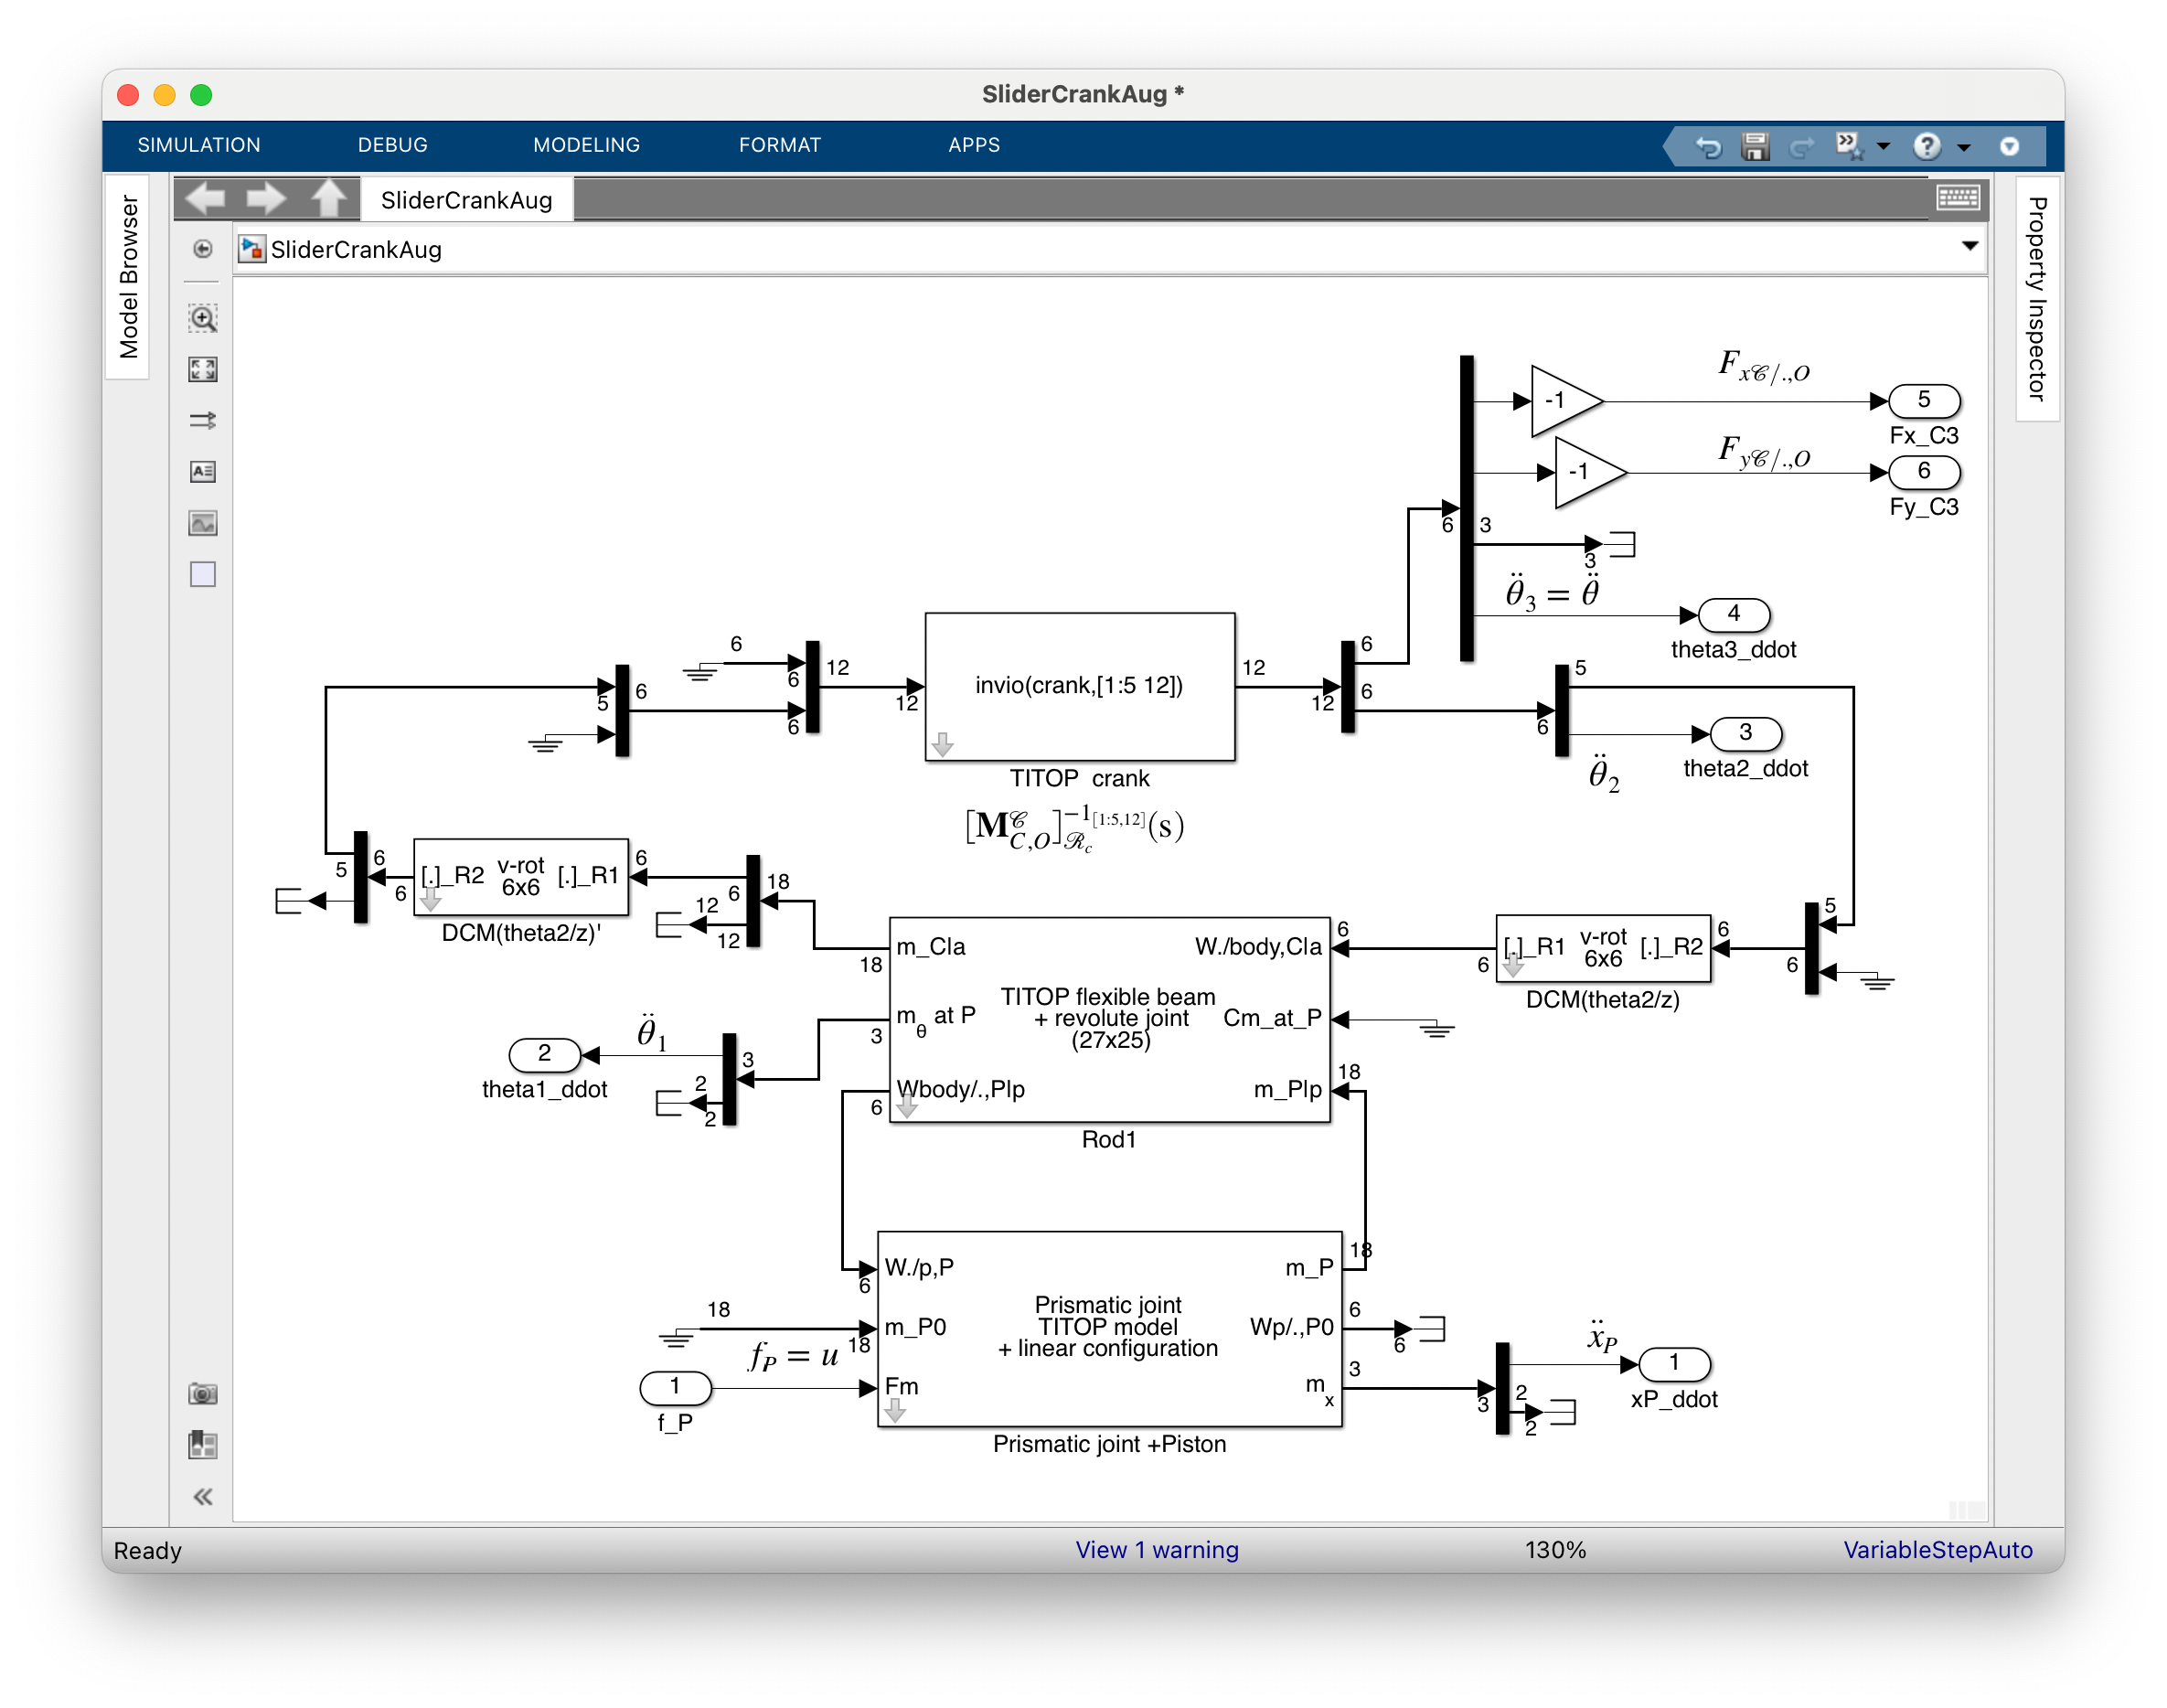

For the particular geometric configuration $\theta=3\pi/4$, the model is diectly obtained using the function` linearize.m`. Note that this function includes also the calculation of a minimal realization of the model $\mathbf G(\mathrm s)$

SliderCrankAug
G=linearize('SliderCrankAug');
damp(G)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.08e+00 + 1.46e+02i     7.44e-03       1.46e+02         9.23e-01    
 -1.08e+00 - 1.46e+02i     7.44e-03       1.46e+02         9.23e-01    
 -9.80e+00 + 5.85e+02i     1.67e-02       5.85e+02         1.02e-01    
 -9.80e+00 - 5.85e+02i     1.67e-02       5.85e+02         1.02e-01    
 -1.19e+01 + 1.62e+03i     7.37e-03       1.62e+03         8.37e-02    
 -1.19e+01 - 1.62e+03i     7.37e-03       1.62e+03         8.37e-02    
 -8.50e+01 + 1.94e+03i     4.38e-02       1.94e+03         1.18e-02    
 -8.50e+01 - 1.94e+03i     4.38e-02       1.94e+03         1.18e-02    
 -2.66e+02 + 4.02e+03i     6.59e-02       4.03e+03         3.77e-03    
 -2.66e+02 - 4.02e+03i     6.59e-02       4.03e+03         3.77e

The order of the $6\times 1$ model `G` is $20$: $5$ flexible modes by link (the rod and the  crank)  including $4$ bending modes in the $(\mathbf x,\;\mathbf y)$-plane and $1$ traction mode along the link $\mathbf x$-axis. Thus, by comparison with the model of the 4-bar mechanism in[*** tutorial11***](matlab:open('../Tutorial11/tutorial11.html')), the out-of-plane flexible modes and the 6 modes at $0$ due to the loop closure constraints are removed by the function `linearize`. See also:

web  DocBeam.html -new

Let us consider $\theta$ varying between $1\,deg$ and $179\,deg$ (with a step of $2\,deg)$, not that $\theta=0$ and $\theta:180\,deg$ are singular configurations), 

theta=[1:2:179]*pi/180;
for ii = 1:length(theta),
    theta3=theta(ii);
    xP=r*cos(theta3)-sqrt(l^2-r^2*sin(theta3)^2);
    theta2=acos((l^2+r^2-xP^2)/2/r/l)-pi;
    theta1=theta3-theta2-pi;
    sysLPV(:,:,ii) = linearize('SliderCrankAug');
end 
sysLPV.SamplingGrid = struct('Crank_configuration',theta);

Then one can plot the frequency-domain responses of the apparent mass $m(\mathrm s,\theta)\,(Kg)$  and the gains between $u$ and the 2 outputs $F_{x\mathcal{C}/.,O}$, $F_{y\mathcal{C}/.,O}$ as functions of $\theta$.

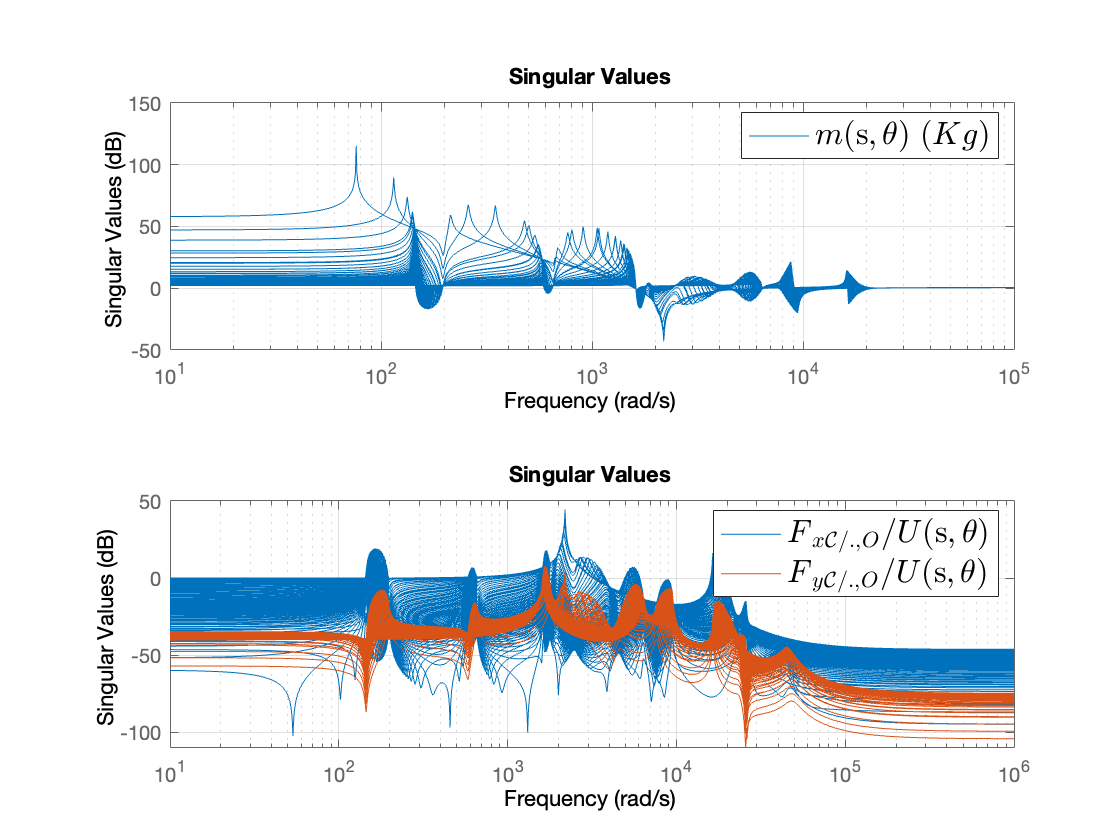

figure
subplot(2,1,1)
sigma(1/sysLPV(1,1,:))   % Apparent mass at point P
grid
legend('$m(\mathrm s,\theta)\;(Kg)$','Interpreter','Latex',...
       'Fontsize',16)
subplot(2,1,2)
sigma(sysLPV(5,1,:))     % transfert from f at P to Fx at O
hold on
sigma(sysLPV(6,1,:))     % transfert from f at P to Fy at O
grid
legend('$F\_{x\mathcal{C}/.,O}/U(\mathrm s,\theta)$',...
       '$F\_{y\mathcal{C}/.,O}/U(\mathrm s,\theta)$',...
       'Interpreter','Latex','Fontsize',16)

One can analyze on these responses:

- the variation of flexible mode frequencies according to $\theta$,

- the variation of the static apparent mass (the DCgain of the transfer from $\ddot x_p$ to $u$, obtained by the first channel inversion of the model $\mathbf G(\mathrm s)$. The apparent mass is very large for the angular configuration $\theta=1\,deg$ and $\theta=179\,deg$ (it is infinite for the singular configurations $\theta=0$ and $\theta:180\,deg$):

1/dcgain(sysLPV(1,1,1))

ans = 785.0588

One of the main interest of ploting the frequency-domain response of the system using its gain-scheduled representation `sysLPV` is that it is possible to click on a particular response in the graphic window to read the corresponding parametric configuration. 